# Introduction to State Estimation or Soft Sensing 

**Sachin C. Patwardhan*, Anjali P. Deshpande and Sharad Bhartiya* **

(*) Dept. of Chemical Engineering,

 Indian Institute of Technology Bombay, Mumbai 400076 India  

## Introduction

       Any state feedback controller implementation requires knowledge of the state vector, $x\left(k\right)$, at the current time instant. For example, if  it is desired to implement a state feedback control law, such as LQR control law, $u\left(k\right)=-G_{\infty } x\left(k\right)$, then we need to know the state $x\left(k\right)$. In a state space formulation of MPC, we use $x\left(k\right)$ as the initial condition for the prediction model for carrying out predictions of the state over the future prediction horizon. To simplify the controller synthesis,  in the previous modules  we have assumed that all states are perfectly measured and therefore available for controller implementation. However, in most real world control problems, we only have access to measurements of a few selected states from the state vector through some hardware devices. For example, in the quadruple tank system, only two out of four levels may be measured using differential pressure transmitters. In such a situation, we need to develop a ***soft sensor*** for the unmeasured levels so that we can implement the state feedback control laws using measured and estimated levels. We reconstruct the unmeasured states using the nominal model (used for the controller synthesis) as a soft sensor and use the available measurements to provide a feedback to this soft sensor. Estimation of the state vector by combining measurements with the internal model based predictions is referred to as **state estimation**. The resulting ***state estimator,  ***i.e.  the soft sensor of unmeasured states, is also referred to as ***observer***. Thus, the following steps are involved in design and implementation of any linear state feedback control law: 

- **Step 1**: Assume perfect state measurements are available and design a stable control controller using a nominal model 

- **Step 2:** Design a stable observer using the nominal model and measurements 

- **Step 3:** Implement the state feedback controller using the estimated states 

You will see in this module, that state estimation brings in additional dynamic equations and in later modules these equations become a part of LQOC or MPC calculations.

**Learning Objectives:**

- To understand the concept of estimation of state of the system from the given state variable model

- To understand the concept of observability of a state variable model

## Fundamentals of State Estimation 

To develop the theory for state estimation, let us go back to the ideal scenario where the plant or system evolves as 

$\begin{array}{l}
x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)\\
y\left(k\right)=C\;x\left(k\right)\\
x\left(0\right):\textrm{Initial}\;\textrm{Condition}\;
\end{array}$  ------(1)

Here $x\in R^n$ represents and state vector and $y\in R^r$ represents the measurement vector. Note that, in practice, the plant state $x\left(k\right)$ is unknown and the user has access only to the input sequence $\left\lbrace u\left(0\right),u\left(1\right)\ldotp \ldotp \ldotp \ldotp u\left(k\right),\ldotp \ldotp \ldotp \ldotp \right\rbrace$ decided by the controller and the measurement sequence  $\left\lbrace y\left(0\right),y\left(1\right)\ldotp \ldotp \ldotp \ldotp \ldotp y\left(k\right),\ldotp \ldotp \ldotp \ldotp \right\rbrace$. Suppose the model matrices {$\Phi ,\Gamma ,C$} are perfectly known, then, can we use this information to estimate the state sequence?   If $x\left(0\right)$ is known perfectly, then we can use the model equation (1) and the input sequence to estimate the state sequence. The trouble is that we do not know the true initial condition $x\left(0\right)$. So to use the model as a soft sensor, we need to start from an initial guess $\hat{x} \left(0\right)\not= x\left(0\right)$ and start using the model 

$\widehat{x} \left(k+1\right)=\Phi \widehat{x} \left(k\right)+\Gamma u\left(k\right)\;\;\textrm{for}\;k=0,1,2,\ldotp \ldotp \ldotp \ldotp \ldotp$  -------(2)

to generate estimates $\widehat{x} \left(k\right)$. Here, $\widehat{x} \left(k\right)$ represent the an estimate of the true system states $x\left(k\right)$. Obviously, $\widehat{x} \left(k\right)\not= x\left(k\right)$ and one way to check how good are the estimates is to find the error or innovation signal 

$e\left(k\right)=y\left(k\right)-\hat{y} \left(k\right)=y\left(k\right)-C\;\hat{x} \left(k\right)$ ------(3) 

If $\|e\left(k\right)\|=\|C\left(x\left(k\right)-\hat{x} \left(k\right)\right)\|$ is small then we can infer that  $\hat{x} \left(k\right)$ is close to $x\left(k\right)\ldotp$

### Observability 

    Instead of guessing the initial state, let us first investigate whether we can use the input and output data together with {$\Phi ,\Gamma ,C$} to uniquely estimate the true state $x\left(0\right)$.  Given input sequence, $\left\lbrace u\left(0\right),u\left(1\right),u\left(2\right),\ldotp \ldotp \ldotp \ldotp \ldotp \right\rbrace$ and model matrices we can use the model to estimate

$\begin{array}{l}
x\left(1\right)=\Phi x\left(0\right)+\Gamma u\left(0\right)\\
x\left(2\right)=\Phi x\left(1\right)+\Gamma u\left(1\right)\\
\;\;\;\;\;\;\;\;\;=\Phi^2 x\left(0\right)+\Phi \Gamma u\left(0\right)+\Gamma u\left(1\right)\\
x\left(3\right)=\Phi^3 x\left(0\right)+\Phi^2 \Gamma u\left(0\right)+\Phi \Gamma u\left(1\right)+\Gamma u\left(2\right)\\
\ldotp \ldotp \ldotp \ldotp =-\ldotp \ldotp \ldotp \ldotp \\
x\left(n\right)=\Phi^n x\left(0\right)+\Phi^{n-1} \Gamma u\left(0\right)+\Phi^{n-2} \Gamma u\left(1\right)+\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp +\Gamma u\left(n-1\right)
\end{array}$ ---------(4)

We can relate this state sequence to 

$\begin{array}{l}
\textrm{Cx}\left(0\right)=y\left(0\right)\\
C\;x\left(1\right)=y\left(1\right)\Longrightarrow C\Phi \;x\left(0\right)=y\left(1\right)-C\Gamma u\left(0\right)\\
\vdots \\
C\Phi^{n-1} \;x\left(0\right)=y\left(n-1\right)-C\Phi^{n-2} \Gamma u\left(0\right)-\ldotp \ldotp \ldotp \ldotp C\Gamma u\left(n-2\right)
\end{array}$-------------(5)

Can we uniquely estimate the  initial state by solving the set of linear algebraic equations (4)?  Combining the equations (5) into a single matrix equation, we can write

$\begin{array}{l}
\;\underbrace{\left\lbrack \begin{array}{c}
C\\
C\Phi \\
C\Phi ²\\
\ldotp \ldotp \ldotp \\
{C\Phi }^{n-1} 
\end{array}\right\rbrack \;\;x} \left(0\right)=\underbrace{\left\lbrack \begin{array}{c}
y\left(0\right)\\
y\left(1\right)-C\Gamma u\left(0\right)\\
y\left(2\right)-C\Phi \Gamma u\left(0\right)-C\Gamma u\left(1\right)\\
\ldotp \ldotp \ldotp \\
y\left(n-1\right)-C\Phi^{n-2} \Gamma u\left(0\right)-\ldotp \ldotp \ldotp \ldotp C\Gamma u\left(n-2\right)
\end{array}\right\rbrack } \\
{\;\;\;\;\;\;\;W}_O \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;b
\end{array}$   ----------(6)

From the matrix equation (5), i.e. $W_0 \;x\left(0\right)=b$, it is clear that a unique solution "$x\left(0\right)$" can be found if and only if $\textrm{rank}\left(W_o \right)=n$, If $\textrm{rank}\left(W_o \right)=n$**, **then the state space model equation (2) is said to be  **observable. **

** Definition** (**Observability**):  The state model (1)  (or the pair ($\Phi ,C$)) is said to be observable if any initial state $x\left(0\right)$ can be uniquely determined from the knowledge of output $y\left(k\right):k=0,1,\ldotp \ldotp \ldotp ,n-1$ and input sequence $u\left(k\right):\textrm{for}\;k=0\ldotp 1\ldotp \ldotp \ldotp \ldotp ,n-1$ where $n$ equals the state dimension. 

The observability property tells us  whether or not the initial states of a system can be uniquely estimated or reconstructed from the measurement outputs under the ideal conditions. 

### Measurement Structure Selection (Sensor Placement)

If a state space model is not observable, then the state estimator will not be able to uniquely determine the states from the system output and that can adversely affect the closed loop performance of a state feedback controller. This leads to a design question. Which states should be measured so that the system is observable? 

Recall the quadruple tank system. Suppose we have only two level sensors (differential pressure transmitters) and we would like to place them such that the four states are observable using only the two level measurements. How to place the sensors?  Observability can be used as a basis for placing the sensors. Let us see the following structures for the measurement or output matrix of [Q Tank Process ](matlab:open('../3. Linearized Models for MPC Formulation/L02_Linearization_of_noninear_Models.mlx'))

Consider the discrete time state space model for the quadruple tank system developed under minimum phase condition (sampling time $T=4$ sec).


$$\Phi =\left\lbrack \begin{array}{cccc}
0\ldotp 9379 & 0 & 0\ldotp 1560 & 0\\
0 & 0\ldotp 9568 & 0 & 0\ldotp 1217\\
0 & 0 & 0\ldotp 8388 & 0\\
0 & 0 & 0 & 0\ldotp 8755
\end{array}\right\rbrack$$
         
$$\Gamma =\left\lbrack \begin{array}{cc}
0\ldotp 3225 & 0\ldotp 0155\\
0\ldotp 0078 & 0\ldotp 2458\\
0 & 0\ldotp 1756\\
0\ldotp 1169 & 0
\end{array}\right\rbrack$$


Since we have only two level sensors with us, we need to choose which two of the four levels should be measured so that the resulting system is observable. In other words, this is a simplified version of problem of designing measurement structure of a system. 

**Structure 1: **The levels in Tank 1 and Tank 2 are measured. Then the output matrix is given as


$$C_1 =\left\lbrack \begin{array}{cccc}
0\ldotp 5 & 0 & 0 & 0\\
0 & 0\ldotp 5 & 0 & 0
\end{array}\right\rbrack$$


The observability matrix rank for this choice measurement placement is 4, and hence the system is observable. 

**Structure 2: **Now we use levels in tanks 3 and 4 as the measured outputs, the output matrix $C$ changes to


$$C_2 =\left\lbrack \begin{array}{cccc}
0 & 0 & 0\ldotp 5 & 0\\
0 & 0 & 0 & 0\ldotp 5
\end{array}\right\rbrack$$


Now, the rank of $W_O$ comes out to be 2. 

**Structure 3: **Let us now measure the levels in tanks 1 and 3 as the measured outputs


$$C_3 =\left\lbrack \begin{array}{cccc}
0\ldotp 5 & 0 & 0 & 0\\
0 & 0 & 0\ldotp 5 & 0
\end{array}\right\rbrack$$


Now, again the rank of $W_O$ comes out to be 2. 

**Structure 4:** Levels in tanks 2 and 4 as the measured outputs 


$$C_4 =\left\lbrack \begin{array}{cccc}
0 & 0\ldotp 5 & 0 & 0\\
0 & 0 & 0 & 0\ldotp 5
\end{array}\right\rbrack$$


Again the rank of observability matrix is 2. The above example shows that there is a rank deficiency when we change the placement of sensors in the process. Thus, **only structure 1, permits state observability**.

Let us now verify this with a simple exercise. 

### Example: Q Tank Process

**Task 1: **Create variables for system matrices phy, gam and C1 and assign the values as given above. 

phy=[ 0.9379 0 0.1560  0 ; 0 0.9568 0 0.1217;  0  0  0.8388  0; 0  0 0  0.8755];
gam=[0.3225 0.0155; 0.0078 0.2458;0  0.1756; 0.1169  0];
C1= [0.5000  0 0  0; 0  0.5000 0  0];

**Task 2:** Create Observability Matrix WO1 as per  equation (6) and find it's rank using [rank ](https://www.mathworks.com/help/matlab/ref/rank.html)function in matlab. Save the rank in variable **Rank_WO1.**

 **rank(A)** provides an estimate of the number of linearly independent rows or columns of a matrix A.

WO1=[C1;C1*phy;C1*phy^2;C1*phy^3];
Rank_WO1=rank(WO1)

Rank_WO1 = 4

**Task 3:** Alternatively we can use **"obsv" command **in Matlab to get the Observability matrix. CO = obsv(SYS) returns the Observability matrix of the state-space model SYS with realization (A,B,C,D).  This is equivalent to obsv(sys.a,sys.c). Use phy and C1 matrices as inputs to obsv command and obtain rank, save it in a **variable Rank_WO1.**

WO_1=obsv(phy,C1);
Rank_WO1=rank(WO_1)

Rank_WO1 = 4

**Task 4:** Now change the C matrix by using sensors for level 1 and level 4. 


$$C=\left\lbrack \begin{array}{cccc}
0\ldotp 5 & 0 & 0 & 0\\
0 & 0 & 0 & 0\ldotp 5
\end{array}\right\rbrack$$


Call it as C5. Now we obtain the rank of the observability matrix WO5, with Rank_WO5. What do you notice?

C5=[0.5  0 0  0; 0  0 0  0.5];
disp('The corresponding Observability Matrix is')
WO5 = obsv(phy,C5)

WO5 =     0.5000         0         0         0
         0         0         0    0.5000
    0.4689         0    0.0780         0
         0         0         0    0.4377
    0.4398         0    0.1386         0
         0         0         0    0.3833
    0.4125         0    0.1849         0
         0         0         0    0.3355


disp('The Rank of Observability Matrix is')
Rank_WO5=rank(WO5)

Rank_WO5 = 3

Note that when the measurement structure is changed, the rank also changes. Here the rank has reduced and hence the system no longer remains observable.

## Difficulties in Estimation of Initial State 

Thus, it appears straightforward to estimate $x\left(0\right)$ if the pair ($\Phi ,C$) is observable and just $n$ measurements are available. Then, why do we need to be concerned about implementation of state feedback control law? The measurements, unfortunately, are always corrupted with some unknown signal or noise.  Thus, a realistic measurement model is 

$y\left(k\right)=C\;x\left(k\right)+v\left(k\right)$ ------(7)

where $\left\lbrace v\left(k\right):k=0,1,\ldotp \ldotp \ldotp \right\rbrace$ represent errors in measurement. Typically these errors arising from multiple sources are random signals and have zero mean. A useful model to represent their behavior is to assume zero mean with Gaussian density. In addition, $\textrm{cov}\left\lbrace v\left(k\right),v\left(j\right)\right\rbrace =0$, i.e. these are independent random variables. Such a signal is called as **while noise**. In the presence of measurement error, equation (5) changes to 

$\begin{array}{l}
\;\underbrace{\left\lbrack \begin{array}{c}
C\\
C\Phi \\
C\Phi ²\\
\ldotp \ldotp \ldotp \\
{C\Phi }^{n-1} 
\end{array}\right\rbrack \;\;x} \left(0\right)=\underbrace{\left\lbrack \begin{array}{c}
y\left(0\right)\\
y\left(1\right)-C\Gamma u\left(0\right)\\
y\left(2\right)-C\Phi \Gamma u\left(0\right)-C\Gamma u\left(1\right)\\
\ldotp \ldotp \ldotp \\
y\left(n-1\right)-C\Phi^{n-2} \Gamma u\left(0\right)-\ldotp \ldotp \ldotp \ldotp C\Gamma u\left(n-2\right)
\end{array}\right\rbrack } -\left\lbrack \begin{array}{c}
v\left(0\right)\\
v\left(1\right)\\
v\left(2\right)\\
\ldotp \ldotp \ldotp \\
v\left(n-1\right)
\end{array}\right\rbrack \\
{\;\;\;\;\;\;\;W}_{\textrm{OA}} \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;b
\end{array}$  ------(8)

Since the noise signal is random and unknown, it is not possible to uniquely estimate the initial condition from equation (8). One possibility is to collect larger number of samples, say $N+1$ and arrange them as follows 

$\begin{array}{l}
\;\underbrace{\left\lbrack \begin{array}{c}
C\\
C\Phi \\
C\Phi ²\\
\ldotp \ldotp \ldotp \\
{C\Phi }^N 
\end{array}\right\rbrack \;\;x} \left(0\right)=\underbrace{\left\lbrack \begin{array}{c}
y\left(0\right)\\
y\left(1\right)-C\Gamma u\left(0\right)\\
y\left(2\right)-C\Phi \Gamma u\left(0\right)-C\Gamma u\left(1\right)\\
\ldotp \ldotp \ldotp \\
y\left(N-1\right)-C\Phi^{N-1} \Gamma u\left(0\right)-\ldotp \ldotp \ldotp \ldotp C\Gamma u\left(N-1\right)
\end{array}\right\rbrack } -\underset{V_N }{\underbrace{\left\lbrack \begin{array}{c}
v\left(0\right)\\
v\left(1\right)\\
v\left(2\right)\\
\ldotp \ldotp \ldotp \\
v\left(N\right)
\end{array}\right\rbrack } } \\
{\;\;\;\;\;\;\;W}_{\mathrm{OA}} \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;b
\end{array}$ ------(9)


$${\;W}_{\mathrm{OA}} x\left(0\right)=b-V_N$$


We can construct a least squares estimate of $x\left(0\right)$ by minimizing $\varphi ={\left(V_N \right)}^T V_N ={\left\|b-{\;W}_{\mathrm{OA}} x\left(0\right)\right\|}^2$ with respect to $x\left(0\right)$ as follows 

$\hat{x} \left(0\right)={\left\lbrack {\left(W_{\textrm{OA}} \right)}^T W_{\textrm{OA}} \right\rbrack }^{-1} {\left(W_{\textrm{OA}} \right)}^T b$ ------(10)

when $\textrm{rank}\left(W_{\textrm{OA}} \right)=n$, i.e. when the linear system is observable. The resulting estimate, however, is not unique. The difficulties in estimating the initial state are further compounded if the system dynamics evolve as 

$\begin{array}{l}
x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)+\Gamma_d d\left(k\right)\\
y\left(k\right)=C\;x\left(k\right)+v\left(k\right)\\
x\left(0\right):\textrm{Initial}\;\textrm{Condition}\;
\end{array}$  ------(11)

where $\left\lbrace d\left(k\right):k=0,1,\ldotp \ldotp \ldotp \right\rbrace$ represents unmeasured disturbance input. Needless to say that equation (9) changes to 

$\begin{array}{l}
\;\underbrace{\left\lbrack \begin{array}{c}
C\\
C\Phi \\
C\Phi ²\\
\ldotp \ldotp \ldotp \\
{C\Phi }^N 
\end{array}\right\rbrack \;\;x} \left(0\right)=\underbrace{\left\lbrack \begin{array}{c}
y\left(0\right)\\
y\left(1\right)-C\Gamma u\left(0\right)-C\Gamma_d d\left(0\right)\\
y\left(2\right)-C\Phi \Gamma u\left(0\right)-C\Gamma u\left(1\right)-C\Phi \Gamma_d d\left(0\right)-C\Gamma_d d\left(1\right)\\
\ldotp \ldotp \ldotp \\
y\left(N-1\right)-C\Phi^{N-1} \Gamma u\left(0\right)-\ldotp \ldotp \ldotp \ldotp C\Gamma u\left(N-1\right)-C\Phi^{N-1} \Gamma_d d\left(0\right)-\ldotp \ldotp \ldotp \ldotp C\Gamma_d d\left(N-1\right)
\end{array}\right\rbrack } -\underset{V_N }{\underbrace{\left\lbrack \begin{array}{c}
v\left(0\right)\\
v\left(1\right)\\
v\left(2\right)\\
\ldotp \ldotp \ldotp \\
v\left(N\right)
\end{array}\right\rbrack } } \\
{\;\;\;\;\;\;\;W}_{\textrm{OA}} \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;b
\end{array}$ ------(12)

With both $\left\lbrace v\left(k\right):k=0,1,\ldotp \ldotp \ldotp \right\rbrace$ and $\left\lbrace d\left(k\right):k=0,1,\ldotp \ldotp \ldotp \right\rbrace$ unknown, this problem of recovering the initial state accurately is difficult to solve. We will later show that a solution can be found if we further assume that $\left\lbrace d\left(k\right):k=0,1,\ldotp \ldotp \ldotp \right\rbrace$ is a zero mean Gaussian white noise signal. The moral of the story is that, in practice, it is difficult to estimate the initial state and the state sequence when state dynamics are influenced by with unknown input signals and the measurements are corrupted with noise. Let us have a look at Q tank example.

clear all
close all

% Quadruple Tank System

**Task 1:** Set the simulation time

N =25;  %Set simulation time 

**Task 2: **On selecting the operating point, corresponding steady state linear discrete model and parameters will be loaded in the workspace. Specify Operating Point,  Minimum Phase or Nonminimum Phase. Set it to Minimum Phase Initially.

operating_pt=1;  % Specify Operating Point,  Minimum Phase or Nonminimum Phase
if operating_pt==1
load QTank_MinPhase_Model
else
 load QTank_NonMinPhase_Model 
end

**Set Simulation Parameters **

% Initial state vector for simulating plant dynamics 
phy= QTank.phy ;  
gam = QTank.gama_u ;
gam_d = QTank.gama_d ; 
C_mat = QTank.C_mat ; 

%  No. of states and inputs    
[n_st,n_ip] = size(gam);
[n_op, nx] = size(C_mat) ;
[nx, n_d] = size(gam_d)  ;
samp_T = 4 ;  

**Task 3: **The measurement and state noise variances can be set as below. Set them to 0.075 

d_sigma =0.075;
v_sigma =0.075;
R_mat = v_sigma^2*eye(n_op) ;
Qd_mat = d_sigma^2*eye(n_d) ;
vk = mvnrnd(zeros(n_op,1), R_mat, N) ;  % Generate measurement noise
vk = vk';
dk = mvnrnd(zeros(n_d,1), Qd_mat , N) ;  % Generate state noise
dk = dk';

**Task 4**. Set the NO_Noise to **"Switch OFF Noise"** for simulating system under the ideal conditions, without measurement noise. 

NO_Noise =  0; % Set this flag for simulating system under noise free conditions 
if (NO_Noise)
    vk = 0 * vk ;  dk = 0 * dk ;  % Set state and measurement noise to zero 
end 

**Simulate Plant Dynamics **

% Generate Input sequence 
uk1 = idinput(N,'rbs', [0,0.2]);
uk2 = idinput(N,'rgs', [0,0.1]);
uk = [ uk1' ; uk2'] ;

% Initialize matrices for saving 
xk = zeros(n_st, N) ;
yk = zeros(n_op,N) ;
xk(:,1) = [ 4 -4 3 -3]';
yk(:,1) = C_mat * xk(:,1) ;

% Simulate plant dynamics 
kT = zeros(N,1) ;
for k = 1 : N-1
    kT(k+1) = (k-1) ;
    xk(:,k+1)= phy * xk(:,k) + gam * uk(:,k) ;
    yk(:,k+1) = C_mat * xk(:,k+1) + vk(:,k+1) ; 
end

**Construct matrices and vectors for initial state estimation: **

Yk_N = reshape(yk, [n_op*N,1]) ;
Uk_N = reshape(uk(:,1:N-1), [n_ip*(N-1),1]) ;

Su_mat = [] ; WO_mat = [] ; 
c2 = 0 ;
mat = zeros(n_st, n_ip * (N-1));
for k = 1 : N -1
    mat = phy*mat;  % Block row matrix for intermediate computations
    % Generation of Su_mat   
    c1 = c2 ; c2 = c1 + n_ip ;
    mat(:,c1+1:c2) = gam;    
    Su_mat = [ Su_mat ;C_mat *  mat ] ; 

    WO_mat = [ WO_mat ; C_mat * phy^(k-1) ] ;
end
WO_mat = [ WO_mat ; C_mat * phy^(N-1) ] ;
disp('Observability Matix is')

Observability Matix is


WO_mat

WO_mat =     0.5000         0         0         0
         0    0.5000         0         0
    0.4700         0    0.0716         0
         0    0.4797         0    0.0513
    0.4418         0    0.1283         0
         0    0.4603         0    0.0952
    0.4153         0    0.1725         0
         0    0.4416         0    0.1325
    0.3903         0    0.2065         0
         0    0.4237         0    0.1639
    0.3669         0    0.2318         0
         0    0.4065         0    0.1902
    0.3449         0    0.2501         0
         0    0.3901         0    0.2120
    0.3242         0    0.2625         0


**Check Rank of WO matrix **

disp('Rank of observability Matix is')

Rank of observability Matix is


R_WO_mat=rank(WO_mat)

R_WO_mat = 4

b_vec = Yk_N - [zeros(n_ip,1); Su_mat * Uk_N] ;
xk0_est = inv(WO_mat'* WO_mat) * WO_mat' * b_vec ;
est_err = xk0_est - xk(:,1) ;
disp('Estimate for Initial State is')

Estimate for Initial State is


initial_estimate=xk0_est'

initial_estimate =     3.9099   -4.0232    3.0881   -2.8874


disp('Actual Initial State used in simulation is')

Actual Initial State used in simulation is


xk(:,1)'

ans =      4    -4     3    -3


disp('Initial State Estimation Error is')

Initial State Estimation Error is


est_err'

ans =    -0.0901   -0.0232    0.0881    0.1126


**Note: Estimation error is practically zero when the noise is switched off. It significant in the presence of noise. **

**Display Simulation Results**

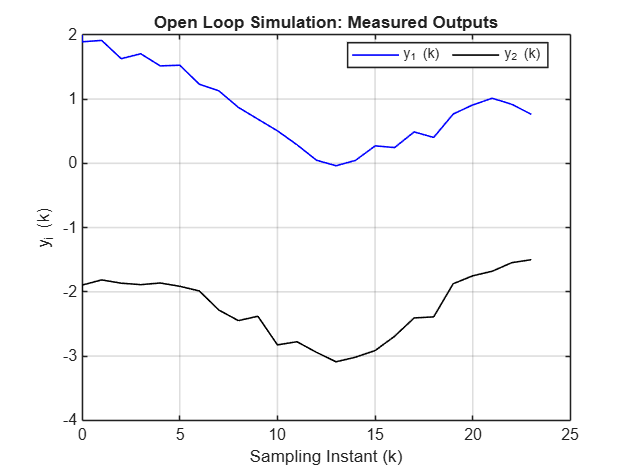

Set_Graphics_Parameters ;
figure(1), plot(kT, yk(1,:), 'b', kT, yk(2,:), 'k'), grid
xlabel('Sampling Instant (k)'), ylabel('y_i (k)')
legend('y_1 (k)', 'y_2 (k)', 'Orientation','horizontal','Location','Best') 
title('Open Loop Simulation: Measured Outputs')

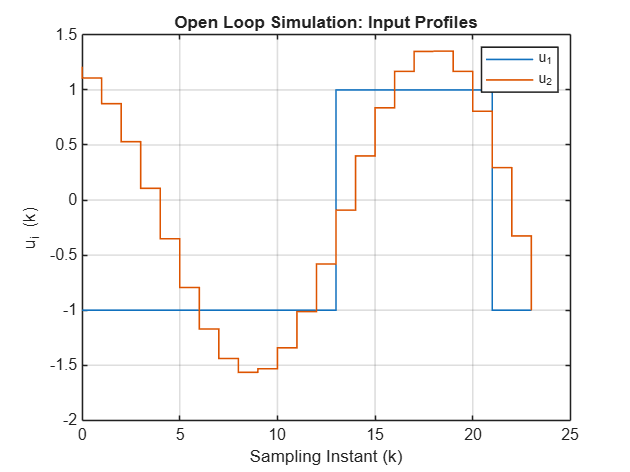

figure(2), stairs(kT, uk', 'LineWidth',1), grid
xlabel('Sampling Instant (k)'), ylabel('u_i (k)'), legend('u_1', 'u_2'), title('Open Loop Simulation: Input Profiles')

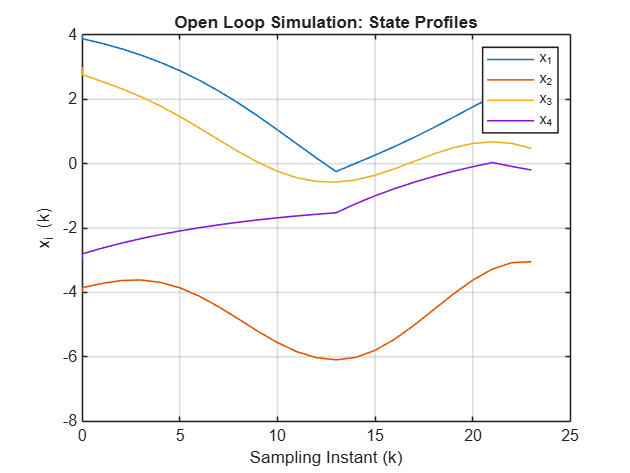

figure(3), plot(kT, xk(1,:), kT, xk(2,:), kT, xk(3,:), kT, xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('x_1', 'x_2', 'x_3', 'x_4'), title('Open Loop Simulation: State Profiles')

**Task 6:** Now switch on the Noise Flag  and observe the simulation results and note the estimation error. 

**Task 7: **Now change the noise levels and again see the changes in estimation of the initial state.

**Task 8: **Repeat the exercise by changing the operating point

From the simulations, it is clear that the initial state can be perfectly recovered under the ideal conditions when there is no measurement noise. However, in the presence of measurement noise, there are always errors in estimation of the initial state. Errors increase with increase in the noise levels.

## Conclusion

In this lesson, we have motivated the study** state estimation** from the given process model and the input output data, when all the states are not measured. We also derive a fundamental property of the system, namely the** observability.  **We notice that the Observability of the model may be  lost, if the measurement structure is not chosen correctly. Thus it is very important to place the sensors after evaluating the observability condition. We also saw that measurement noise and In the next lesson, we will study [design of an observer](matlab:open('./L02_Pole_Placement_Observer_Design.mlx')).

## References

Astrom, K. J. and B. Wittenmark, Computer Controlled Systems, Prentice Hall, 1990.

Franklin, G. F. and J. D. Powell, Digital Control of Dynamic Systems, Addison-Wesley, 1989.